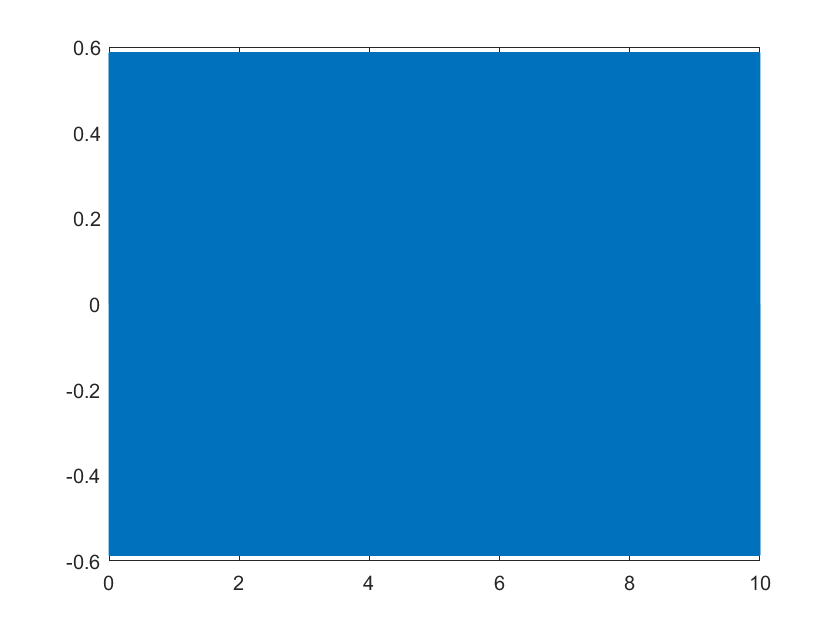

% step1: 采样设置
fs = 44100;				% 采样率, 点数/s
duration = 1 * 10;		% 信号持续时间，s
t = linspace(0, duration, fs * duration);	%数字信号采样点时刻

% step2: 模拟信号 sin(2*pi*f1*t) + sin(2*pi*f2*t) 
f1 = 440;
f2 = 880;

% step3: 采样
signal = sin(2*pi*f1*t) + sin(2*pi*f2*t);

% step4: 量化
bits = 16;
amplitude = 3;		%量化单位：2*amplitude/2^bits
pcm = round(signal/(2*amplitude/2^bits));

% step5: 编码保存
% filename = 'ret/ad_trans.pcm';
% fid = fopen(filename,'w');
% fwrite(fid, pcm, 'int16');
% fclose(fid);

fu = pcm./abs(pcm);

d1 = pcm/(2^(bits-1));

ydB =  1 .* (20*log10(abs(d1)));
plot(t, d1);